clear;clf;
max_res = 1600;
min_res = 100;
half_max_res = max_res / 2;
half_min_res = min_res / 2;
def_domain = 1;
min_angle = 14.25;
to_rad = 1/180*pi();

frac_res = 21;
nof_continue_zero = floor(-log2(double(ufi(def_domain / half_min_res, frac_res, frac_res))));


inv_focal_length = def_domain / half_max_res;
fix_inv_focal_length = ufi(inv_focal_length, frac_res-nof_continue_zero, frac_res)

fix_inv_focal_length =     0.0012

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Unsigned
            WordLength: 16
        FractionLength: 21

error_max_angle = (double(fix_inv_focal_length)*half_max_res - def_domain) * half_max_res

error_max_angle = -0.1343

error_max_angle = double(fix_inv_focal_length)/(1/800)

error_max_angle = 0.9998

fix_inv_focal_length.bin

ans = '0000101000111101'





inv_maxerror_focal_length = tan(min_angle/2*to_rad) / half_max_res;
fix_inv_maxerror_focal_length = ufi(inv_maxerror_focal_length, frac_res-nof_continue_zero, frac_res)

fix_inv_maxerror_focal_length =    1.5640e-04

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Unsigned
            WordLength: 16
        FractionLength: 21

log2(double(fix_inv_maxerror_focal_length))

ans = -12.6424

error_min_angle = (double(fix_inv_maxerror_focal_length)*half_max_res - tan(min_angle/2*to_rad)) * half_max_res

error_min_angle = 0.0979

fix_inv_maxerror_focal_length.bin

ans = '0000000101001000'

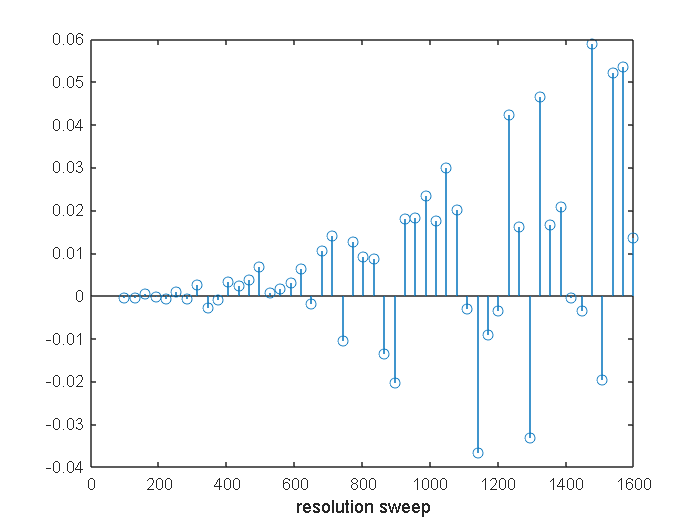

clear;clf;

e = dwAnalysis(15,25);
stem(linspace(100,1600,50),e);
xlabel("resolution sweep")

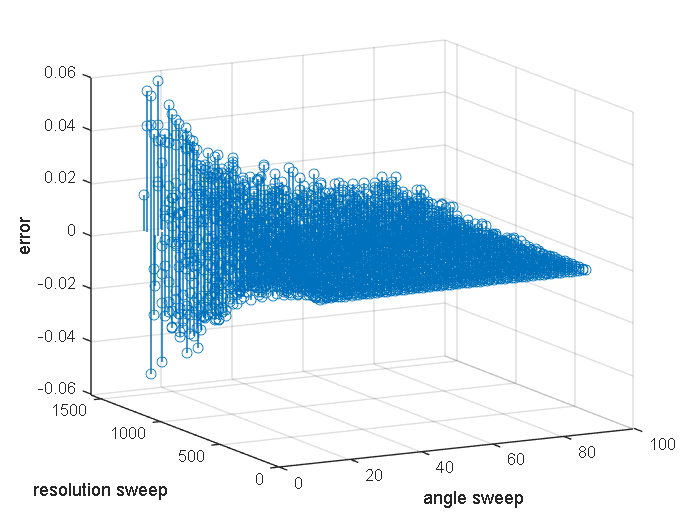


angle_step = 1;
angles = 15:angle_step:90;
fracLs = 17:1:26;

E = dwAnalysis(angles,25);

stem3(angles, linspace(100,1600,50), E);
view([-27.909 14.613]);
xlabel("angle sweep");
ylabel("resolution sweep");
zlabel("error");

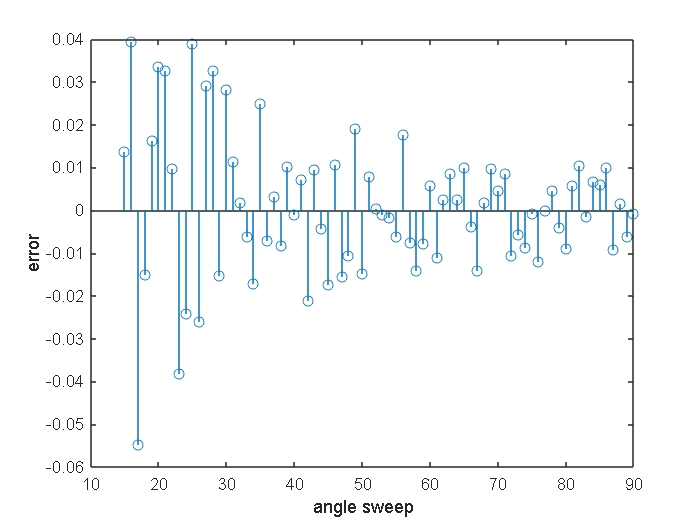



stem(angles, E(50,:))
xlabel("angle sweep");
ylabel("error");

max(abs(E(:)))

ans = 0.0590

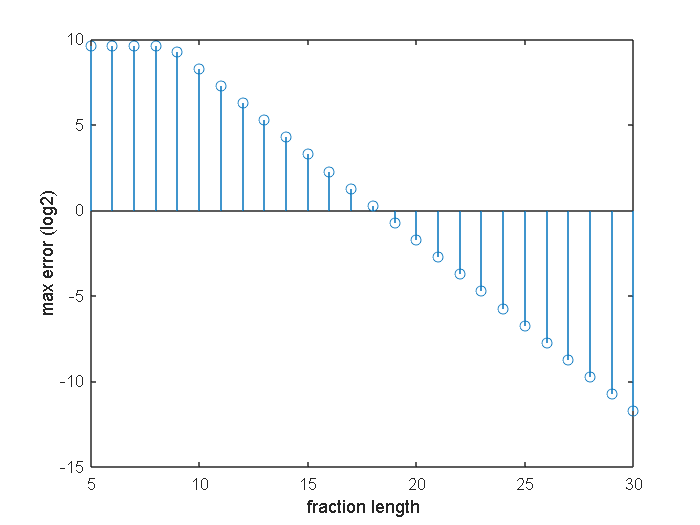

% clear;clf;
tendency = [];
for i=5:30
    E_temp = dwAnalysis(angles,i);
    tendency = [tendency max(abs(E_temp(:)))];
end
stem(5:30, log2(tendency))
xlabel("fraction length");
ylabel("max error (log2)");

function max_error = dwAnalysis(angle, fracLength)%1: angle, 2:frac_res
max_res = 1600;
min_res = 100;
half_max_res = max_res / 2;
half_min_res = min_res / 2;
def_domain = 1;
min_angle = angle;
to_rad = 1/180*pi();
frac_res = fracLength;
res_sweep = linspace(half_min_res, half_max_res, 50);

error_current_angle = [];
for i=1:numel(res_sweep)

    inv_maxerror_focal_length = tan(min_angle./2*to_rad) / res_sweep(i);
    fix_inv_maxerror_focal_length = ufi(inv_maxerror_focal_length, frac_res, frac_res);
    temp = (double(fix_inv_maxerror_focal_length) * res_sweep(i) - tan(min_angle./2*to_rad)) ./ inv_maxerror_focal_length; 
    error_current_angle = [error_current_angle; temp];
end
max_error = error_current_angle;
end